# Credit Scorecard Development

## Scope

ModelName = 'Refaat 2011 Credit Card Model';
ModelVersion = '1.0';
ModelStatus = 'Draft';
Title = 'Refaat 2011 Credit Card Model';
Subject = 'Model Development Documentation';


**Load the Data from Refaat 2011**

Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84876  table              
  dataMissing       -              84876  table              
  dataWeights       -              94720  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

filteredData = dataMissing;
filteredData(:,'CustAge') = [];%

summary(dataMissing(:,'CustAge'))


Description:  Credit card dataset, from: M. Refaat, Credit Risk Scorecards, lulu.com, 2011.

Variables:

    CustAge: 1200×1 double

        Values:

            Min              21    
            Median           45    
            Max              74    
            NumMissing       30    



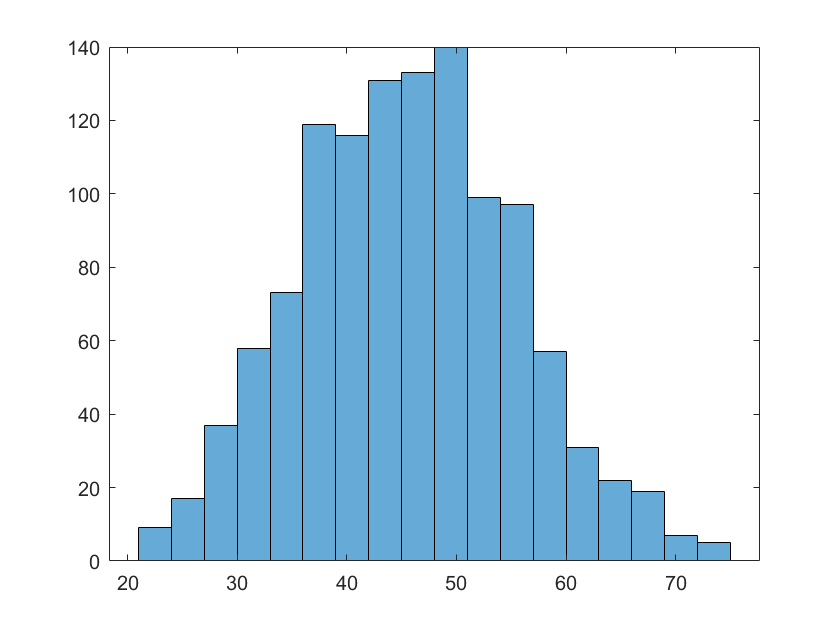

histogram(dataMissing{:,'CustAge'})

Set the response variable to the status column

responseVar = "ResponseVar";

Remove the ID variable from the list of predictors

idVar = "IDVar";

Create a separate bin for missing data values

binMissingData = true;

Use observation weights if they are present

weightsVar = "WeightsVar";
if ~ismember( weightsVar, filteredData.Properties.VariableNames )
    weightsVar = '';
end

Create the credit scorecard object

sc = creditscorecard(filteredData,...
    'IDVar',idVar,...
    'ResponseVar',responseVar,...
    'BinMissingData',binMissingData,...
    'WeightsVar',weightsVar);
disp(sc)

  creditscorecard with properties:

                GoodLabel: 0
              ResponseVar: 'ResponseVar'
               WeightsVar: ''
                 VarNames: {1×10 cell}
        NumericPredictors: {1×5 cell}
    CategoricalPredictors: {'ResStatus'  'EmpStatus'  'OtherCC'}
           BinMissingData: 1
                    IDVar: 'IDVar'
            PredictorVars: {1×8 cell}
                     Data: [1200×10 table]

